rawDataPath_cells_media = '/home/mxwbio/Data/JG_25_12_08_M231s/251208/003425/Record/000002/data.raw.h5';
rawDataPath_media_media = '/home/mxwbio/Data/JG_25_12_08_M231s/251208/003486/Record/000001/data.raw.h5';

rawDataPath_cells_T0 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000006/data.raw.h5';
rawDataPath_cells_T30 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000010/data.raw.h5';
rawDataPath_cells_T60 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000014/data.raw.h5';

rawDataPath_cells_D1 = '/home/mxwbio/Data/JG_25_12_08_M231s/251216/P003425/Record/000018/data.raw.h5';
rawDataPath_cells_D2 = '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003425/Record/000026/data.raw.h5';
rawDataPath_cells_D3 = '/home/mxwbio/Data/JG_25_12_08_M231s/251218/P003425/Record/000030/data.raw.h5';
rawDataPath_cells_D4 = '/home/mxwbio/Data/JG_25_12_08_M231s/251219/P003425/Record/000038/data.raw.h5';

rawDataPath_media_T0 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000008/data.raw.h5';
rawDataPath_media_T30 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000012/data.raw.h5';
rawDataPath_media_T60 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000016/data.raw.h5';

rawDataPath_media_D1 = '/home/mxwbio/Data/JG_25_12_08_M231s/251216/P003486/Record/000020/data.raw.h5';
rawDataPath_media_D2 = '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003486/Record/000025/data.raw.h5';
rawDataPath_media_D3 = '/home/mxwbio/Data/JG_25_12_08_M231s/251218/P003486/Record/000032/data.raw.h5';
rawDataPath_media_D4 = '/home/mxwbio/Data/JG_25_12_08_M231s/251219/P003486/Record/000040/data.raw.h5';

rawData_cells_media = mxw.fileManager(rawDataPath_cells_media);
rawData_cells_T0 = mxw.fileManager(rawDataPath_cells_T0);
rawData_cells_T30 = mxw.fileManager(rawDataPath_cells_T30);
rawData_cells_T60 = mxw.fileManager(rawDataPath_cells_T60);

rawData_cells_D1 = mxw.fileManager(rawDataPath_cells_D1);
rawData_cells_D2 = mxw.fileManager(rawDataPath_cells_D2);
rawData_cells_D3 = mxw.fileManager(rawDataPath_cells_D3);
rawData_cells_D4 = mxw.fileManager(rawDataPath_cells_D4);

rawData_media_media = mxw.fileManager(rawDataPath_media_media);
rawData_media_T0 = mxw.fileManager(rawDataPath_media_T0);
rawData_media_T30 = mxw.fileManager(rawDataPath_media_T30);
rawData_media_T60 = mxw.fileManager(rawDataPath_media_T60);

rawData_media_D1 = mxw.fileManager(rawDataPath_media_D1);
rawData_media_D2 = mxw.fileManager(rawDataPath_media_D2);
rawData_media_D3 = mxw.fileManager(rawDataPath_media_D3);
rawData_media_D4 = mxw.fileManager(rawDataPath_media_D4);

electrodes = 894:894;
numSeconds = 1;
avPSD_RMSs_media = zeros(7,1);
avPSD_RMSs_cells = zeros(7,1);

timepoints = [(1/60) (30/60) (60/60) 24 48 72 96];
[PSD_cells_media,freq,PSDs_cells_media] = processRawData(rawData_cells_media,electrodes,numSeconds,2);

   1.8530e-06



[PSD_cells_T0,~,PSDs_cells_T0,avPSD_RMSs_cells(1)] = processRawData(rawData_cells_T0,electrodes,numSeconds,0.5);

   2.1078e-06



[PSD_cells_T30,~,PSDs_cells_T30,avPSD_RMSs_cells(2)] = processRawData(rawData_cells_T30,electrodes,numSeconds,0.5);

   2.3843e-06



[PSD_cells_T60,~,PSDs_cells_T60,avPSD_RMSs_cells(3)] = processRawData(rawData_cells_T60,electrodes,numSeconds,0.5);

   2.2956e-06



[PSD_cells_D1,~,PSDs_cells_D1,avPSD_RMSs_cells(4)] = processRawData(rawData_cells_D1,electrodes,numSeconds,0.5);

   2.2242e-06



[PSD_cells_D2,~,PSDs_cells_D2,avPSD_RMSs_cells(5)] = processRawData(rawData_cells_D2,electrodes,numSeconds,2);

   2.2053e-06



[PSD_cells_D3,~,PSDs_cells_D3,avPSD_RMSs_cells(6)] = processRawData(rawData_cells_D3,electrodes,numSeconds,2);

   2.1961e-06



[PSD_cells_D4,~,PSDs_cells_D4,avPSD_RMSs_cells(7)] = processRawData(rawData_cells_D4,electrodes,numSeconds,2);

   2.2380e-06



[PSD_media_media,~,PSDs_media_media] = processRawData(rawData_media_media,electrodes,numSeconds,2);

   1.9554e-06



[PSD_media_T0,~,PSDs_media_T0,avPSD_RMSs_media(1)] = processRawData(rawData_media_T0,electrodes,numSeconds,0.5);

   2.1270e-06



[PSD_media_T30,~,PSDs_media_T30,avPSD_RMSs_media(2)] = processRawData(rawData_media_T30,electrodes,numSeconds,0.5);

   2.0748e-06



[PSD_media_T60,~,PSDs_media_T60,avPSD_RMSs_media(3)] = processRawData(rawData_media_T60,electrodes,numSeconds,0.5);

   2.1045e-06



[PSD_media_D1,~,PSDs_media_D1,avPSD_RMSs_media(4)] = processRawData(rawData_media_D1,electrodes,numSeconds,0.5);

   2.0824e-06



[PSD_media_D2,~,PSDs_media_D2,avPSD_RMSs_media(5)] = processRawData(rawData_media_D2,electrodes,numSeconds,0.5);

   2.0901e-06



[PSD_media_D3,~,PSDs_media_D3,avPSD_RMSs_media(6)] = processRawData(rawData_media_D3,electrodes,numSeconds,2);

   2.0777e-06



[PSD_media_D4,~,PSDs_media_D4,avPSD_RMSs_media(7)] = processRawData(rawData_media_D4,electrodes,numSeconds,2);

   2.0729e-06



[PSD_cells_media,freq,PSDs_cells_media,avPSD_RMS_cells] = processRawData(rawData_cells_media,electrodes,numSeconds,2);

   1.8530e-06



[PSD_media_media,~,PSDs_media_media,avPSD_RMS_media] = processRawData(rawData_media_media,electrodes,numSeconds,2);

   1.9554e-06



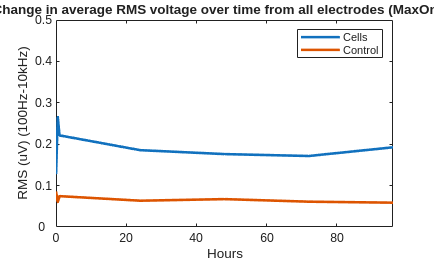

clf;
plot(timepoints,avPSD_RMSs_cells(:)-avPSD_RMS_cells,LineWidth=2);
hold on;
plot(timepoints,avPSD_RMSs_media(:)-avPSD_RMS_media,LineWidth=2);
hold off;
ylim([0 1E-6]);
xlim([0 96])
yt = get(gca,'YTick');
set(gca,'YTickLabel',yt*1E6);
xlabel('Hours');
ylabel('RMS (uV) (100Hz-10kHz)');

legend('Cells','Control')
title('Change in average RMS voltage over time from all electrodes (MaxOne+)');

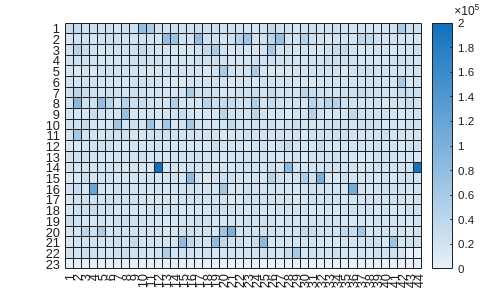

clf('reset');
heatmapData_Ctrl = getHeatmap(PSDs_cells_media,freqs);

heatmap(heatmapData_Ctrl,'ColorLimits',[0 200000]);

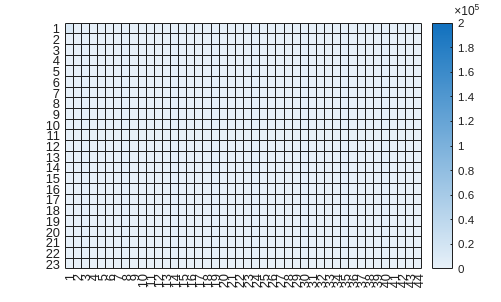

clf('reset');
heatmapData = getHeatmap(PSDs_cells_T0,freqs);

heatmap(heatmapData-heatmapData_Ctrl,'ColorLimits',[0 200000]);

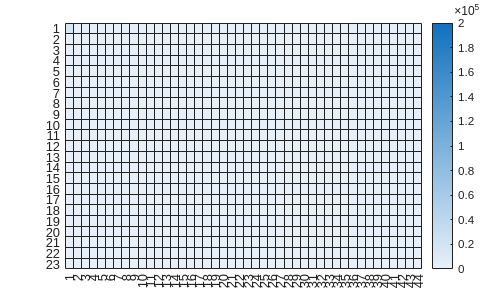

clf('reset');
heatmapData = getHeatmap(PSDs_cells_T30,freqs);

heatmap(heatmapData-heatmapData_Ctrl,'ColorLimits',[0 200000]);

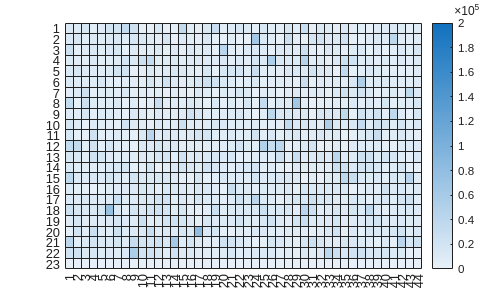

clf('reset');
heatmapData = getHeatmap(PSDs_cells_T60,freqs);

heatmap(heatmapData-heatmapData_Ctrl,'ColorLimits',[0 200000]);

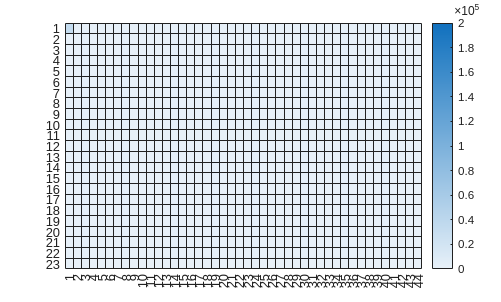

clf('reset');
heatmapData = getHeatmap(PSDs_cells_D1,freqs);

heatmap(heatmapData-heatmapData_Ctrl,'ColorLimits',[0 200000]);

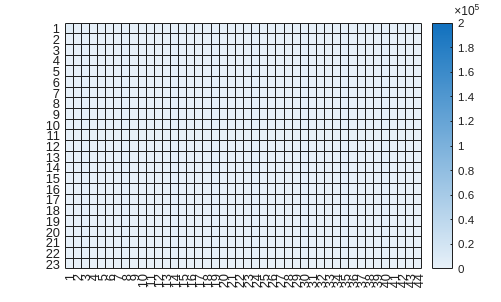

clf('reset');
heatmapData = getHeatmap(PSDs_cells_D2,freqs);

heatmap(heatmapData-heatmapData_Ctrl,'ColorLimits',[0 200000]);

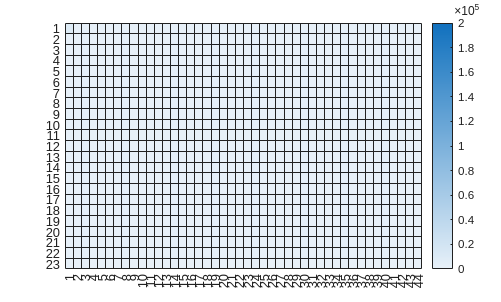

clf('reset');
heatmapData = getHeatmap(PSDs_cells_D3,freqs);

heatmap(heatmapData-heatmapData_Ctrl,'ColorLimits',[0 200000]);

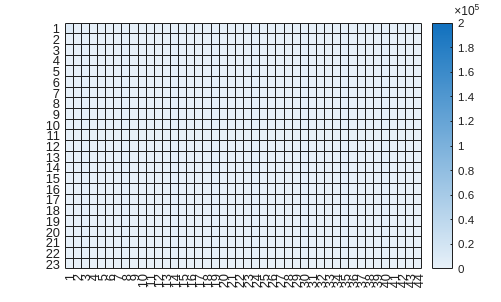

clf;
heatmapData = getHeatmap(PSDs_cells_D4,freqs);

heatmap(heatmapData-heatmapData_Ctrl,'ColorLimits',[0 200000]);

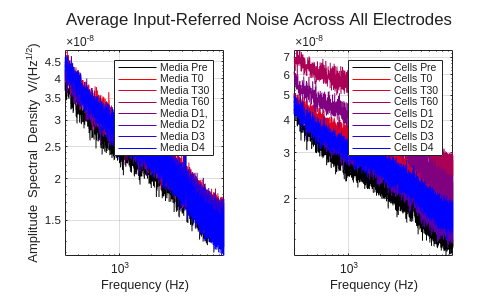

clf;
t1 = tiledlayout(1,2);
title(t1,'Average Input-Referred Noise Across All Electrodes');
nexttile;

loglog(freq,sqrt(PSD_media_media));
hold on;
loglog(freq,sqrt(PSD_media_T0));
hold off;

hold on;
loglog(freq,sqrt(PSD_media_T30));
hold off;
hold on;
loglog(freq,sqrt(PSD_media_T60));
hold off;

hold on;
loglog(freq,sqrt(PSD_media_D1));
hold off;
hold on;
loglog(freq,sqrt(PSD_media_D2));
hold off;
hold on;
loglog(freq,sqrt(PSD_media_D3));
hold off;
hold on;
loglog(freq,sqrt(PSD_media_D4));
hold off;
xlabel('Frequency (Hz)');
ylabel('Amplitude Spectral Density V/(Hz^{1/2})');
legend("Media Pre","Media T0","Media T30","Media T60","Media D1,","Media D2","Media D3","Media D4");
set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on');
xlim([300 9990]);

ax = gca;
colourMapLen = 7;
red = [1,0,0];
blue = [0,0,1];
colourGradient = [linspace(red(1),blue(1),colourMapLen)',linspace(red(2),blue(2),colourMapLen)',linspace(red(3),blue(3),colourMapLen)'];
ax.ColorOrder = cat(1,[0,0,0], colourGradient);

nexttile;
loglog(freq,sqrt(PSD_cells_media));


hold on;
loglog(freq,sqrt(PSD_cells_T0));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_T30));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_T60));
hold off;

hold on;
loglog(freq,sqrt(PSD_cells_D1));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D2));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D3));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D4));
hold off;

ax = gca;
ax.ColorOrder = cat(1,[0,0,0], colourGradient);
xlabel('Frequency (Hz)');
xlim([300 9990]);
set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on');
legend("Cells Pre","Cells T0","Cells T30","Cells T60","Cells D1","Cells D2","Cells D3","Cells D4");

%legend("Media T0","Media T60","Media D1,","Media D2","Media D3","Media D4","Cells T0","Cells T60","Cells D1","Cells D2","Cells D3","Cells D4","Cells Pre","Media Pre");

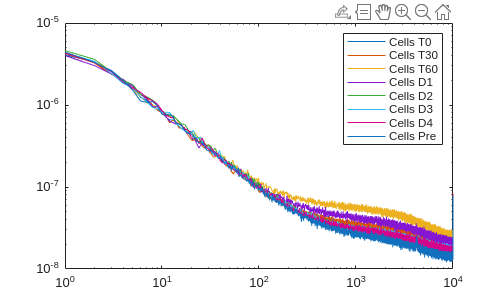

clf;



loglog(freq,sqrt(PSD_cells_T0));

hold on;
loglog(freq,sqrt(PSD_cells_T30));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_T60));
hold off;

hold on;
loglog(freq,sqrt(PSD_cells_D1));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D2));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D3));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D4));
hold off;

hold on;
loglog(freq,sqrt(PSD_cells_media));
hold off;


%legend("Media T0","Media T30","Media T60","Media D1,","Media D2","Media D3","Media D4","Cells T0","Cells T30","Cells T60","Cells D1","Cells D2","Cells D3","Cells D4");
legend("Cells T0",'Cells T30',"Cells T60","Cells D1","Cells D2","Cells D3","Cells D4","Cells Pre");

% 
% electrodes = [1 50];
% numSeconds = 500

numSeconds = 500

% 
% rawTracesSubset = getRawTracesSubset(rawData_media,electrodes,numSeconds,(0.5*1024));
% filteredTraces = getFilteredTraces(rawTracesSubset,0.001);
% [avPSD,freqs,PSDs,avPSD_RMS] = getAveragePSD(filteredTraces,numSeconds);

    0.0078



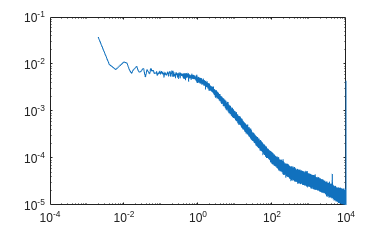

% loglog(freqs,sqrt(avPSD))



function [rawTracesSubset] = getRawTracesSubset(rawData,electrodes,numSeconds,correction)
   
    fs = 20000;
    electrodeNums= transpose(rawData.rawMap(1).map.electrode(500:550));
    [rawTraces,~,~] = rawData.extractRawData(fs,(numSeconds*fs),'files',1,'electrodes',electrodeNums);
    rawTracesSubset = rawTraces;
   
    rawTracesSubset = (rawTracesSubset./(1000000)).*correction;

    %returns input-referred traces with correction factor




end

function [filteredTraces] = getFilteredTraces(rawTraces,fc)

    fs = 20000;

    [sos,g] = butter(1,(fc)/(fs/2),"high");
    filteredTraces = filtfilt(sos,g,rawTraces);
end

function [avPSD,freqs,PSDs,avPSD_RMS] = getAveragePSD(filteredTraces,numSeconds)

    fs = 20000;
    resolution = 1/numSeconds;

    nfft = fs/resolution;
    window = hann(nfft); %len?
    overlap = 0;

    
    [PSDs,freqs] = pwelch(filteredTraces,window,overlap,nfft,fs);
    avPSD = sum(PSDs,2)/size(PSDs,2);

    avPSD_RMS = sqrt(trapz(freqs(300:end-1),avPSD(300:end-1)));
    disp(avPSD_RMS);
end

function [PSD,freq,PSDs,avPSD_RMS] = processRawData(rawData,electrodes,numSeconds,correction)
    rawTracesSubset = getRawTracesSubset(rawData,electrodes,numSeconds,correction);
    filteredTraces = getFilteredTraces(rawTracesSubset,0.1);
    [PSD,freq,PSDs,avPSD_RMS] = getAveragePSD(filteredTraces,numSeconds);
end


function [heatmapData,unmappedData] = getHeatmap (PSDs, freqs)

    electrodeSize = 1012;
    PSDs(:,end + 1:electrodeSize) = 0;

    if size(PSDs,2) == electrodeSize

        freqs = repmat(freqs,1,electrodeSize);
        PSDs_RMS = zeros(electrodeSize,1);

        for i = 1:electrodeSize
            PSDs_RMS(i) = sqrt(trapz(freqs(300:end-1,i),PSDs(300:end-1,i)));
        end

        %IR_Electrode_PSD_RMS = ((((PSDs_RMS./gain).^2) - ((2.2E-6).^2))).^(1/2);
        %IR_Electrode_PSD_RMS = PSDs_RMS./gain;
        IR_Electrode_PSD_RMS = PSDs_RMS;

        IR_Electrode_PSD_RMS = real((max(IR_Electrode_PSD_RMS,0)));

        bandwidth = 9999-300;
        boltzman = 1.38E-23;
        temp = 310; % 37 degree C in kelvin

        resistances = (IR_Electrode_PSD_RMS.^2)./(4*boltzman*temp*bandwidth);
        
        mappedResistances = getMappedElectrodes(resistances);
        heatmapData = mappedResistances;
        
        unmappedData = resistances;


    else
        disp("Need 966 electrodes for heatmaps.")
    end
end


function mappedElectrodes = getMappedElectrodes(electrodes)
    mappedElectrodes = zeros([23,44]);
    
    for i = 1:23
        x = (i-1)*44;
        y = i*44;
        mappedElectrodes(i,1:44) = transpose(electrodes(x+1:y));
    end
end